# Jeff Suitor - 400138679 - 4QZ3 Final

clc
clear all
close all

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


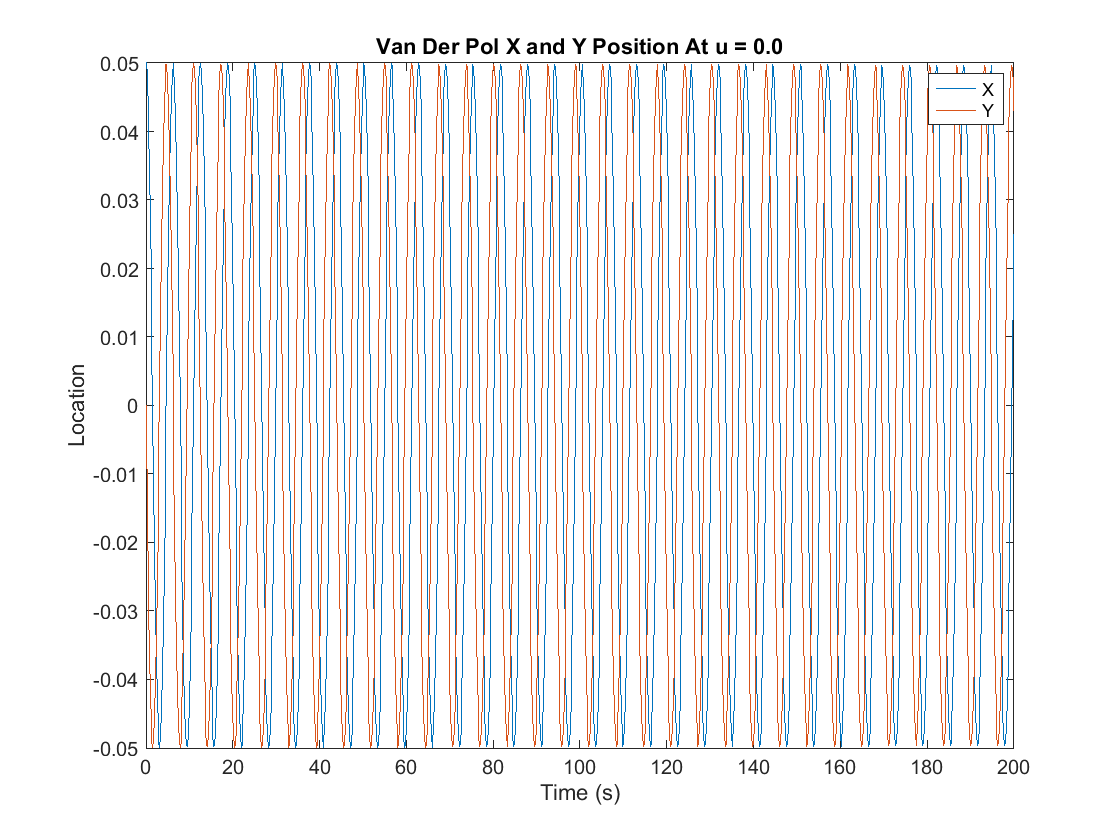

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


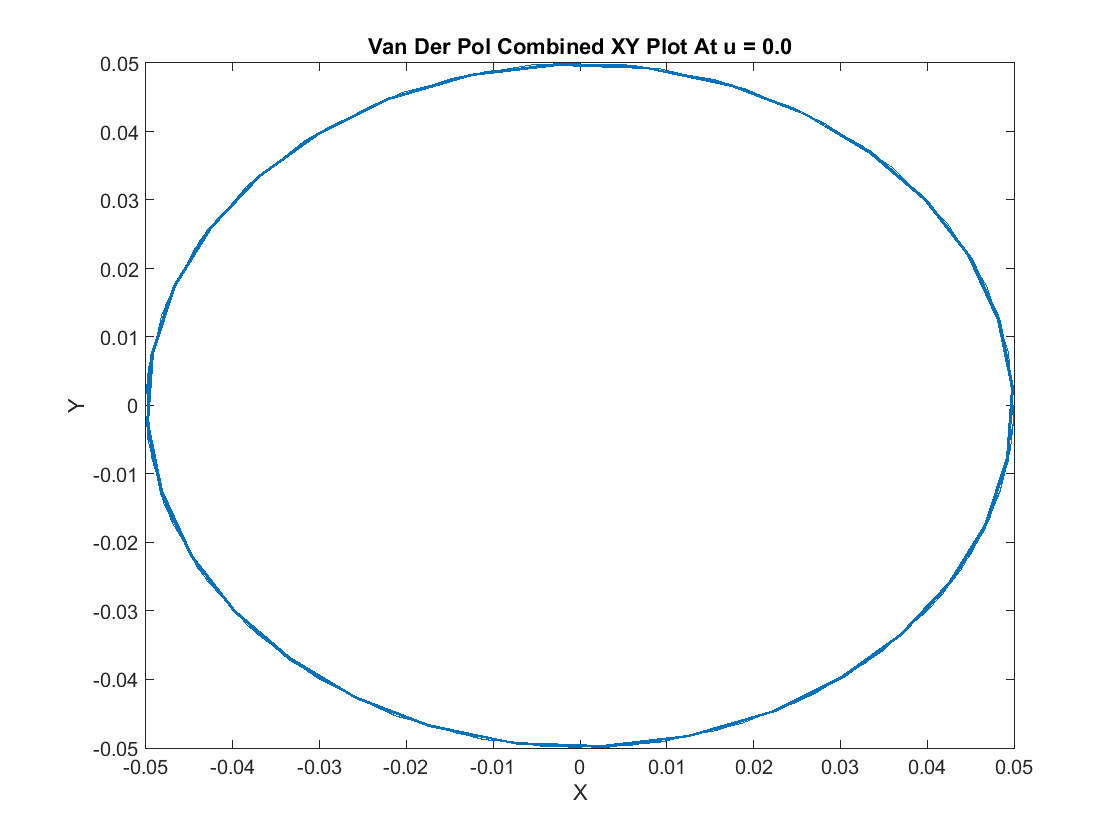

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


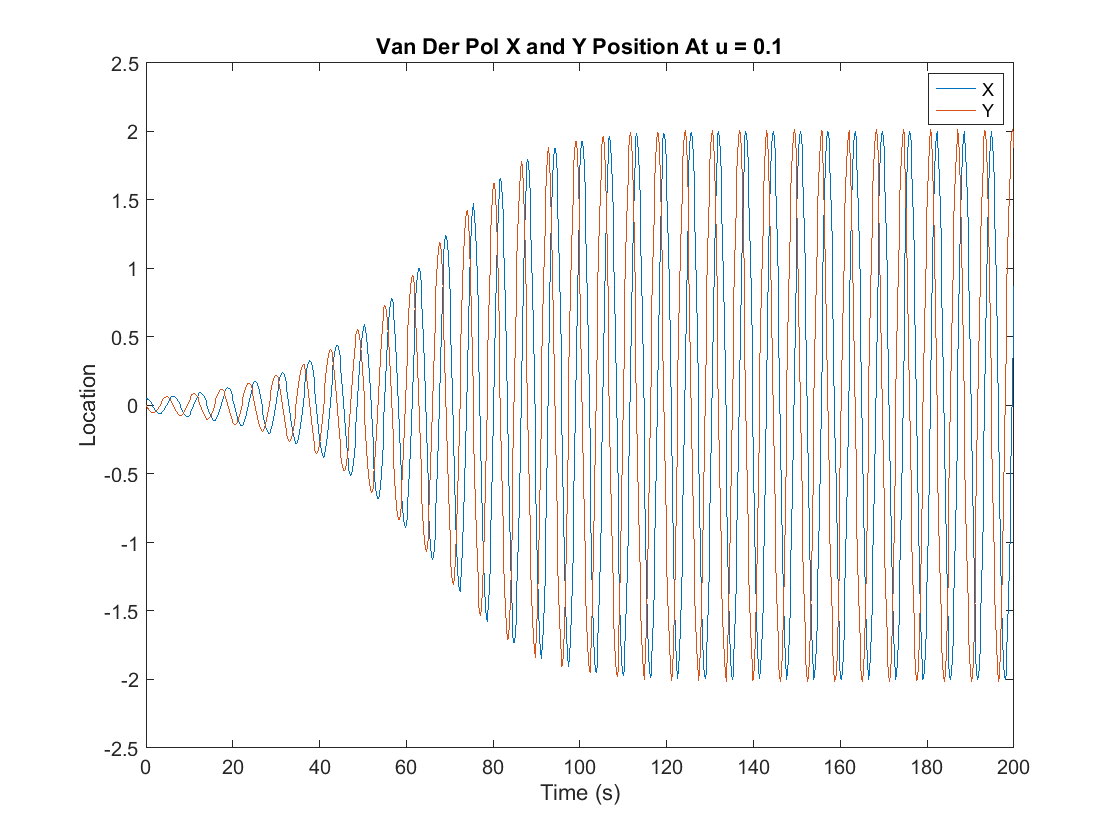

f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


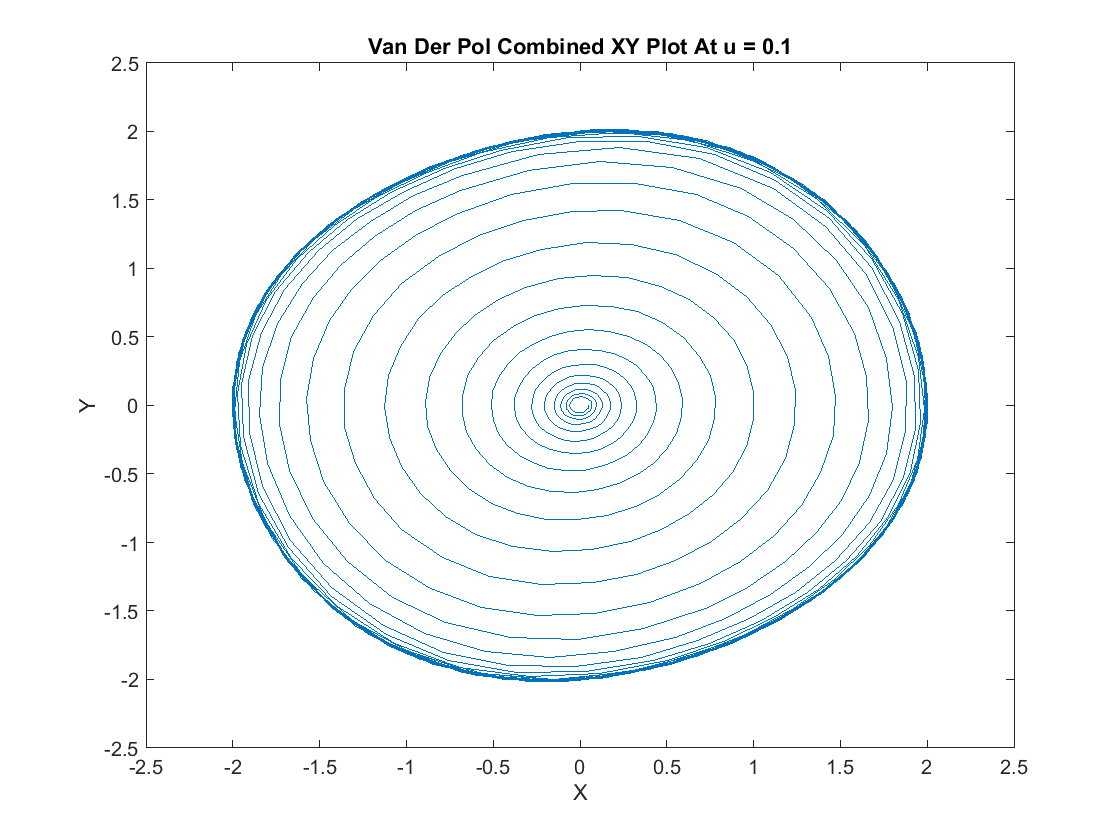

f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


f =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


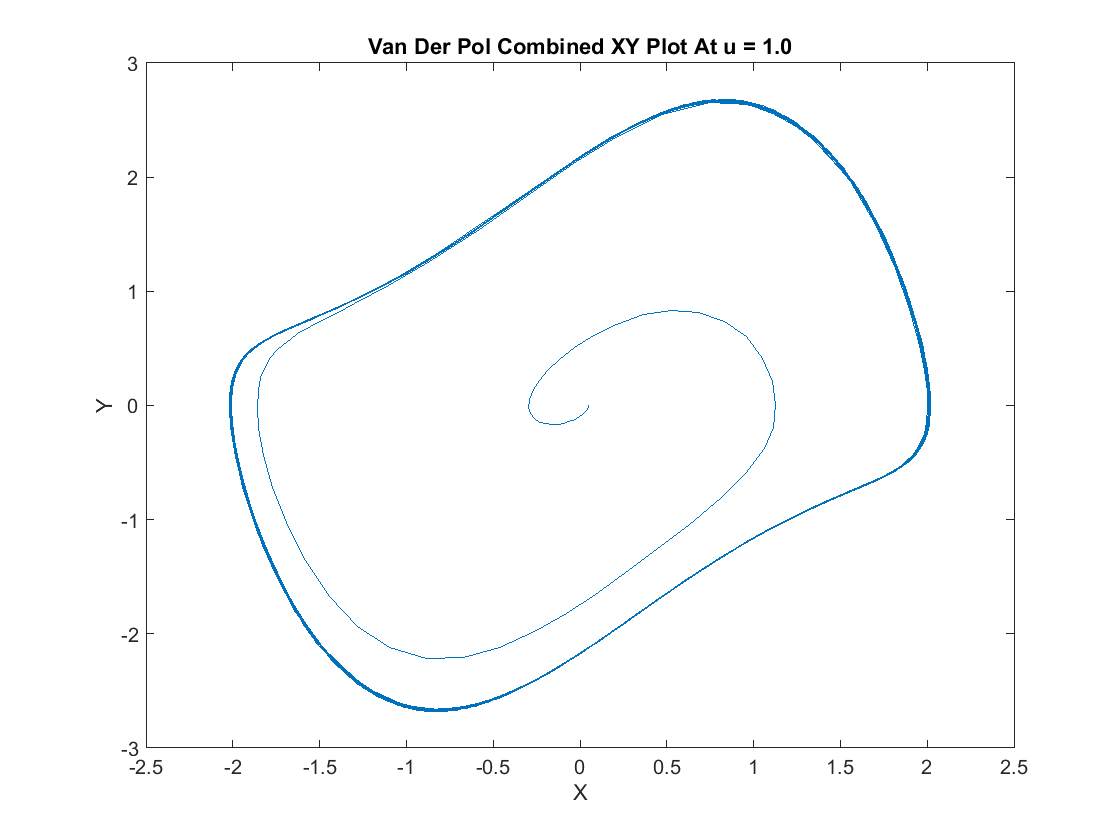

f =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


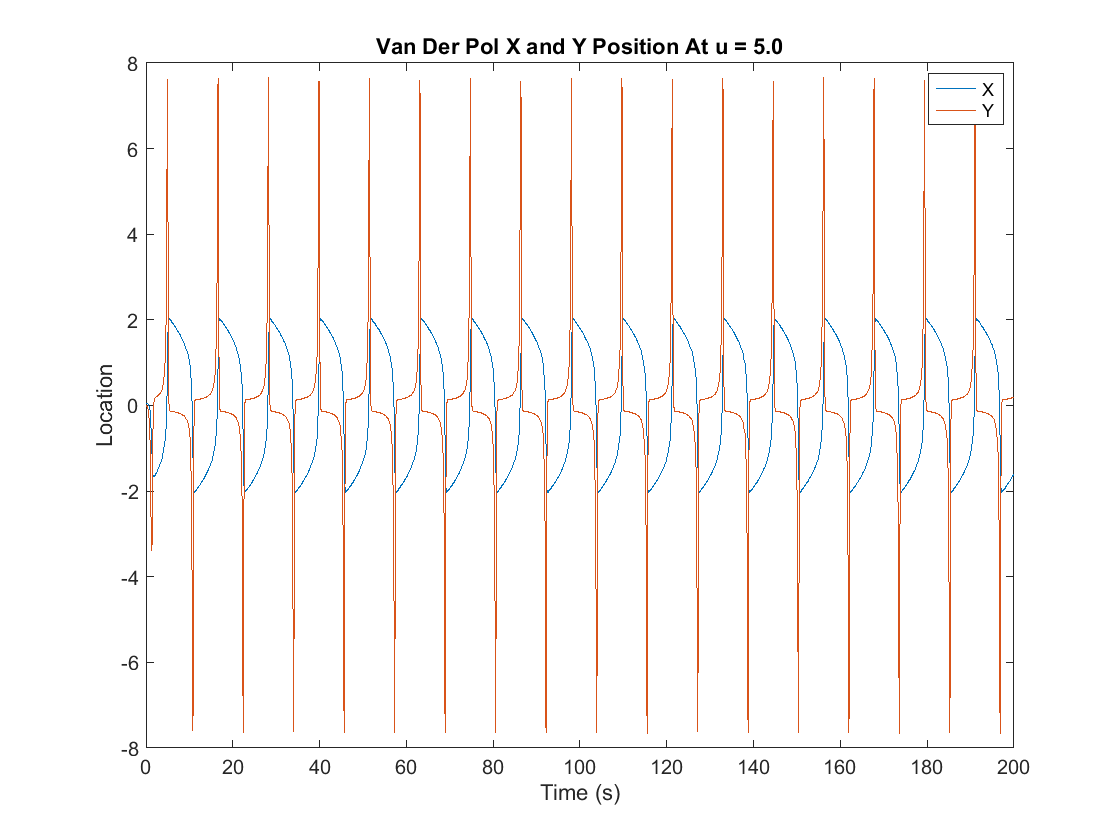

f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


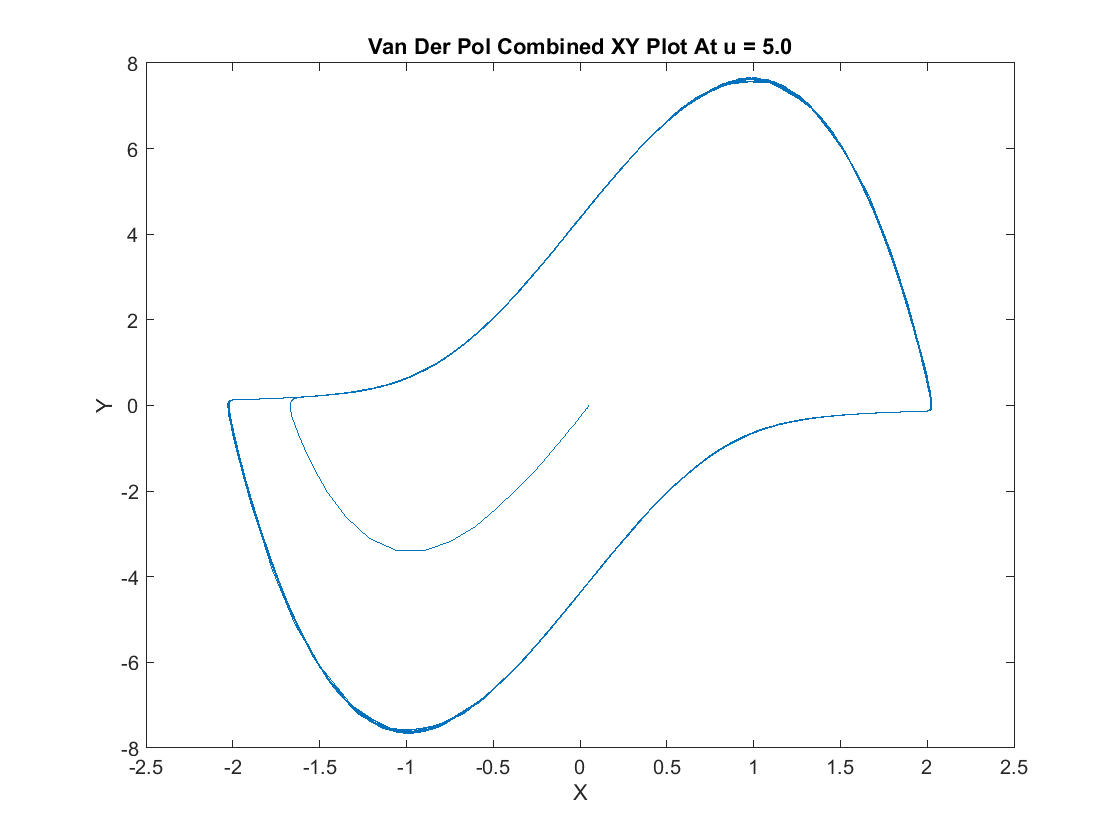

f =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


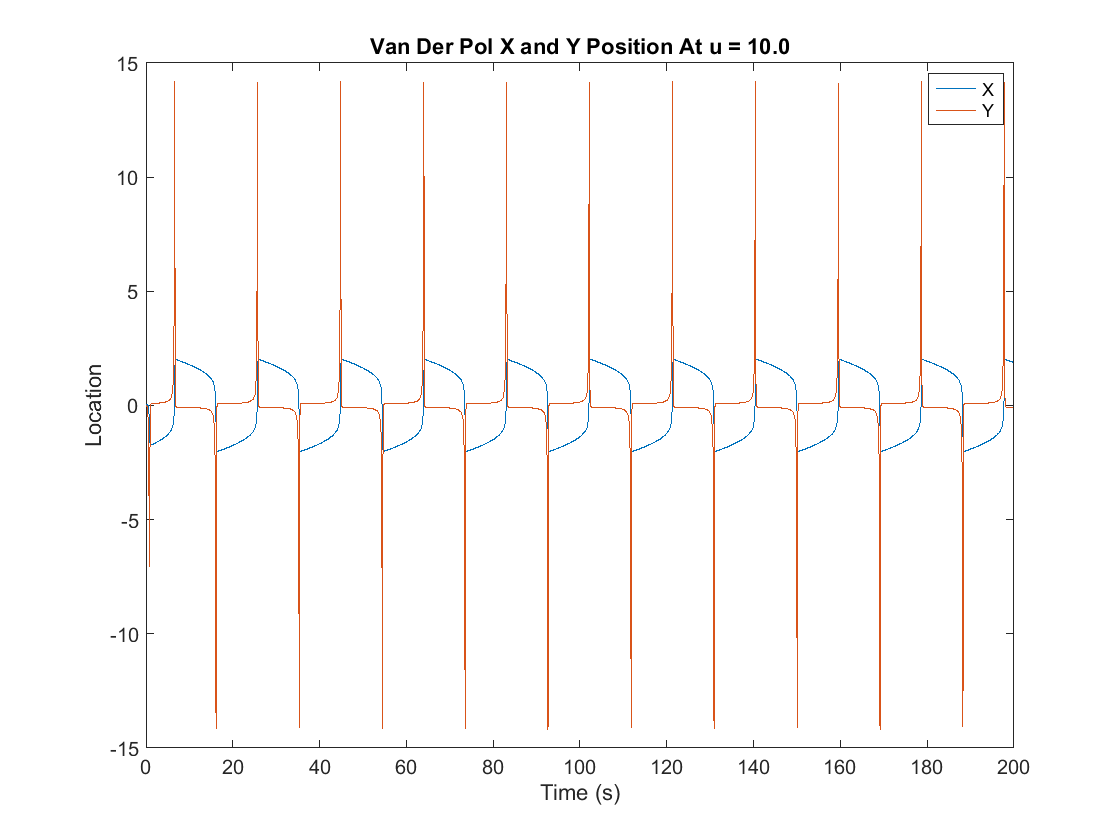

f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


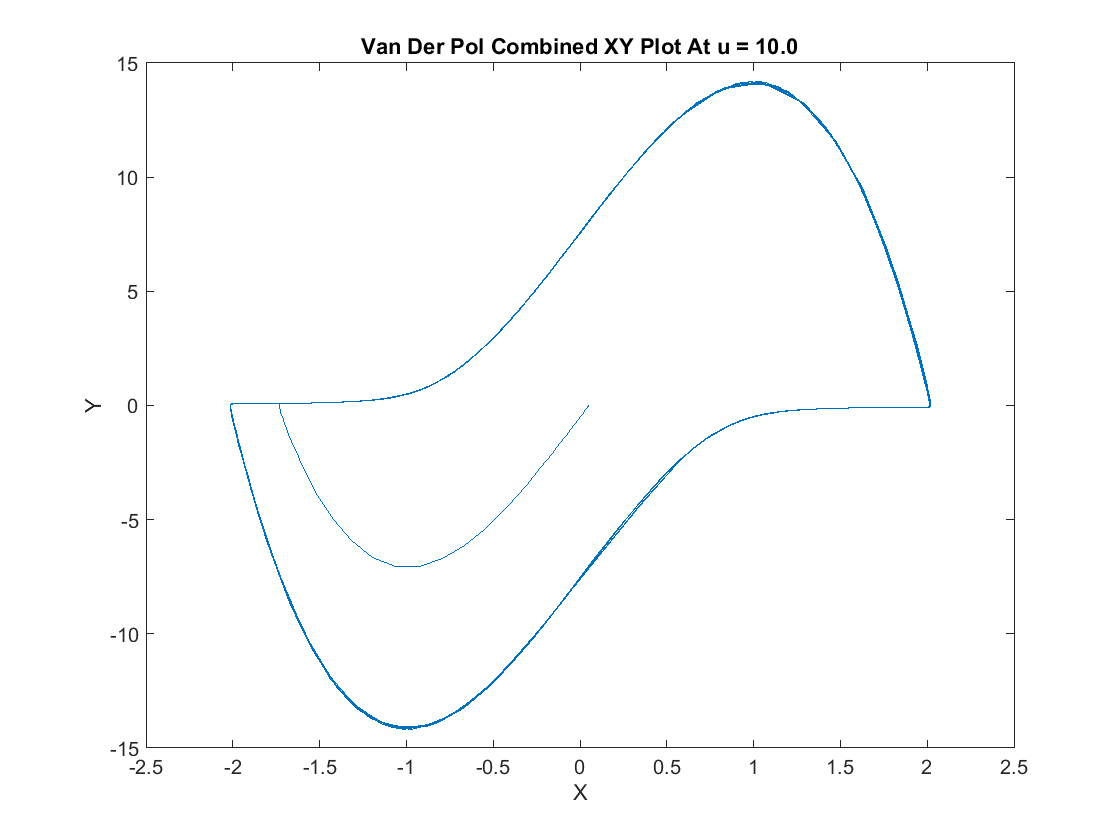

tspan = [0 200];Jeff Suitor - 400138679 - 4QZ3 Final
clc
clear all
close all

tspan = [0 200];
x_0 = 0.05;
y_0 = 0;
Y0 = [x_0; y_0]; %x y
U = [0, 0.1, 1, 5, 10];

for u = U
    [t, Y] = ode45(@(t,y) vdp(t,y,u), tspan, Y0);
    L = length(Y(:,1));
    x = zeros(L, 1);
    y = zeros(L, 1);
    x(:) = Y(:,1);
    y(:) = Y(:,2);
    
    f = figure
    plot(t, x, t, y)
    title_str = sprintf('Van Der Pol X and Y Position At u = %0.1f',u);
    title(title_str);
    xlabel('Time (s)');
    ylabel('Location');
    legend('X','Y')
    saveas(f, strcat(title_str, ".png"))
    
    f = figure
    plot(x, y)
    title_str = sprintf('Van Der Pol Combined XY Plot At u = %0.1f',u);
    title(title_str);
    xlabel("X")
    ylabel("Y")
    saveas(f, strcat(title_str, ".png"))

end

function dydt = vdp(t, Y, u)
dydt = zeros(2, 1); %[dot x; dot y]
dydt(1) = Y(2); % Use the current value of y
dydt(2) = u*(1-Y(1)^2)*Y(2)-Y(1);
end

x_0 = 0.05;
y_0 = 0;
Y0 = [x_0; y_0]; %x y
U = [0, 0.1, 1, 5, 10];

for u = U
    [t, Y] = ode45(@(t,y) vdp(t,y,u), tspan, Y0);
    L = length(Y(:,1));
    x = zeros(L, 1);
    y = zeros(L, 1);
    x(:) = Y(:,1);
    y(:) = Y(:,2);
    
    f = figure
    plot(t, x, t, y)
    title_str = sprintf('Van Der Pol X and Y Position At u = %0.1f',u);
    title(title_str);
    xlabel('Time (s)');
    ylabel('Location');
    legend('X','Y')
    saveas(f, strcat(title_str, ".png"))
    
    f = figure
    plot(x, y)
    title_str = sprintf('Van Der Pol Combined XY Plot At u = %0.1f',u);
    title(title_str);
    xlabel("X")
    ylabel("Y")
    saveas(f, strcat(title_str, ".png"))

end

function dydt = vdp(t, Y, u)
dydt = zeros(2, 1); %[dot x; dot y]
dydt(1) = Y(2); % Use the current value of y
dydt(2) = u*(1-Y(1)^2)*Y(2)-Y(1);
end